# Actividad Práctica N°3: Diseño de controladores considerado la dinámica del error y la magnitud de la acción de control en sistemas no lineales multivariables

## Caso de estudio 1. Sistema de tres variables de estado.

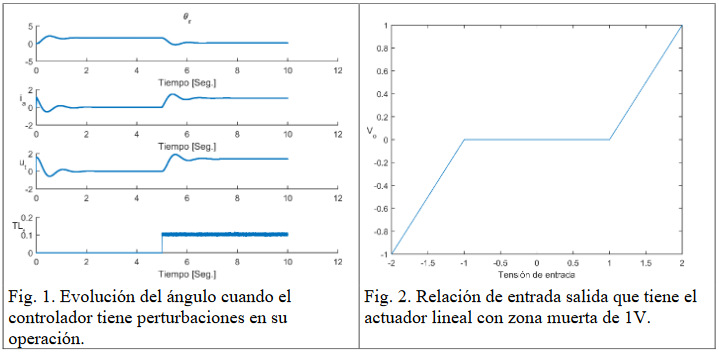

**Ítem [1] **Implementar un sistema en variables de estado que controle el ángulo del motor para consignas de $\frac{\pi }{2}$ y $-\frac{\pi }{2}$ cambiando cada 5 segundos y que el $T_L =0\ldotp 115\;\textrm{Nm}$ aparece sólo para $\frac{\pi }{2}$, para $-\frac{\pi }{2}$ es nulo. Hallar el valor de integración Euler adecuado.

Objetivo: acelerar la dinámica del controlador que muestra la figura 1 aunque ésta se muestre en otra escala de tiempo, verificando el resultado con las curvas del archivo xlsx adjunto.

- Evitando que la tensión supere los $24\;V$ en valor absoluto, especificar el tiempo de muestreo necesario para que el controlador cumpla el objetivo.

- Asumiento que no puede medirse directamente, proponer un controlador que logre el objetivo.

- Determinar el efecto de la no linealidad en la acción de control, descripta en la figura 2, y verificar cuál es el máximo valor admisible de esa no linealidad.

clear all;
close all;
clc;

Primero se abre el archivo de Excel con las curvas medidas, de forma de poder comparar posteriormente los resultados obtenidos.

file = 'E:\Documentos\GitHub\TPsControl2\TPsControl2\actividad3\motor.xls';
sheet = 'Hoja1';
[num, txt, raw] = xlsread(file, sheet);
timeExcel = num(:, 1); 
angExcel = num(:, 2); 
omegaExcel = num(:, 3);
iaExcel = num(:, 4);
vExcel = num(:, 5);
torqueExcel = num(:, 6);

Se declaran ahora los parametros del motor.

Laa = 0.56e-3;
J = 0.0019;
Ra = 1.35;
Bm = 0.000792;
Ki = 0.1;
Km = 0.1;

El modelado en espacio de estados para el sistema en tiempo continuo es:

A = [-Ra/Laa -Km/Laa 0; Ki/J -Bm/J 0; 0 1 0]

A = 	1.0e+03 *

   -2.4107   -0.1786         0
    0.0526   -0.0004         0
         0    0.0010         0


B = [1/Laa; 0; 0]

B = 	1.0e+03 *

    1.7857
         0
         0


C = [0 0 1; 0 1 0]

C =      0     0     1
     0     1     0


D = [0]

D = 0

sys = ss(A,B,C,D)

sys =
 
  A = 
            x1       x2       x3
   x1    -2411   -178.6        0
   x2    52.63  -0.4168        0
   x3        0        1        0
 
  B = 
         u1
   x1  1786
   x2     0
   x3     0
 
  C = 
       x1  x2  x3
   y1   0   0   1
   y2   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



pole(sys)

ans = 	1.0e+03 *

         0
   -0.0043
   -2.4068


Los tiempos de integración y muestreo son:

Ts = 1e-4;
h = 1e-5;

Se discretiza el sistema.

dSys = c2d(sys,Ts,'zoh')

dSys =
 
  A = 
              x1         x2         x3
   x1     0.7857   -0.01587          0
   x2   0.004677     0.9999          0
   x3  2.432e-07     0.0001          1
 
  B = 
              u1
   x1     0.1587
   x2  0.0004343
   x3  1.476e-08
 
  C = 
       x1  x2  x3
   y1   0   0   1
   y2   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Sample time: 0.0001 seconds
Discrete-time state-space model.



A = dSys.A;
B = dSys.B;
C = dSys.C;

Para eliminar el error en estado estable se amplian las matrices y se implementa un integrador.

Aamp = [A,zeros(3,1);-C(1,:)*A, 1]

Aamp =     0.7857   -0.0159         0         0
    0.0047    0.9999         0         0
    0.0000    0.0001    1.0000         0
   -0.0000   -0.0001   -1.0000    1.0000


Bamp = [B;-C(1,:)*B]

Bamp =     0.1587
    0.0004
    0.0000
   -0.0000


Camp = [C(1,:) 0]

Camp =      0     0     1     0


El controlador DLQR queda declarado como a continuacion:

Q = diag([1 1 1 0.1]);    
R = 0.001;
Kamp = dlqr(Aamp,Bamp,Q,R);
K = Kamp(1:3);
Ki = -Kamp(4);

Como no puede medirse la corriente, se implementa un observador para controlarla.

Ao = A';
Bo = C';
Co = B';
Qo = 1*diag([10 10 10]);    
Ro = 0.1;
Ko = dlqr(Ao,Bo,Qo,Ro);

Para poder simular el sistema, los parametros temporales son:

T = 10;
h = 1e-5;
Kmax = T/Ts;
t = 0:h:(T);

La referencia y el torque aplicado, son respectivamente:

thetaRef = (pi/2)*square(2*pi*(1/10)*t);
torqueRef = ((1.5)/2)*square(2*pi*(1/10)*t)+((1.5)/2);

La alinealidad del controlador como zona muerta es:

deadZone = 1

deadZone = 1

Luego, vector de estados y vector observado.

x(1,1) = 0;
x(2,1) = 0;
x(3,1) = 0;
x(4,1) = 0;
xObs(1,1) = 0;
xObs(2,1) = 0;
xObs(3,1) = 0;

Para simular:

xTs = x((1:3),1);
vTs = x(4,1);
z = 1;
for i=1:1:Kmax
    xK = xTs;
    vK = vTs;
    u = -K(1:3)*xObs(1:3)+Ki*vK; 
    uPrev = u;

  El actuador llega a la alinealidad.

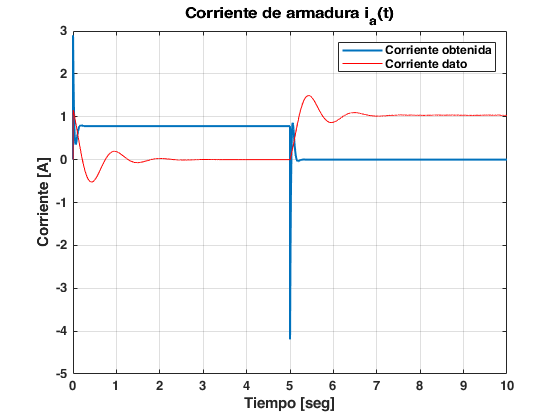

    if abs(u)<deadZone
        u = 0;
    else
        u = sign(u)*(abs(u)-deadZone);
    end
    yS = C*x(1:3,z); 
    for j = 1:1:Ts/h 
        prevU(z) = uPrev;
        x1P = -Ra*x(1,z)/Laa-Km*x(2,z)/Laa+u/Laa;
        x2P = Ki*x(1,z)/J-Bm*x(2,z)/J-torqueRef(z)/J;

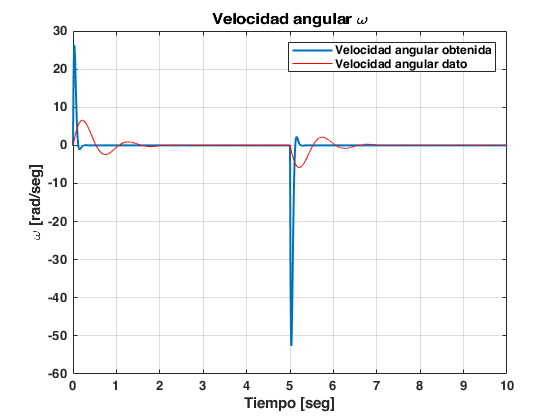

        x3P = x(2,z);
        xP = [x1P; x2P; x3P];
        x((1:3),z+1) = x((1:3),z)+h*xP;
        z = z+1;
    end
    yHat = C*xObs;
    xObs = A*xObs+B*u+Ko'*(yS-yHat);
    vTs = vTs+thetaRef(z)-C(1,:)*xTs;
    xTs = x((1:3),z);
end

Para comparar, se obtienen las graficas:

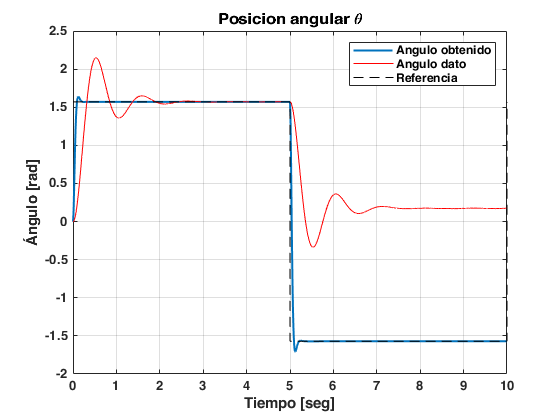

plot(t(1:length(x(1,:))),x(1,:),'LineWidth',1.5);
hold on;
plot(timeExcel,iaExcel,'r');
hold off
grid;
xlim([0 T]);
legend('Corriente obtenida','Corriente dato');
title('Corriente de armadura i_a(t)');
xlabel('Tiempo [seg]');
ylabel('Corriente [A]');
plot(t(1:length(x(2,:))),x(2,:),'LineWidth',1.5);

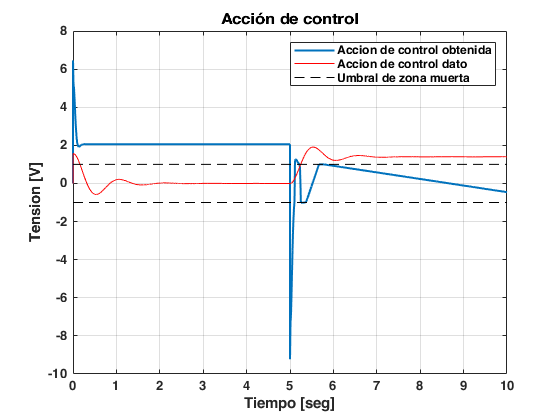

hold on;
plot(timeExcel,omegaExcel,'r');
hold off;
grid;
xlim([0 T]);
legend('Velocidad angular obtenida','Velocidad angular dato');
title('Velocidad angular \omega');
xlabel('Tiempo [seg]');
ylabel('\omega [rad/seg]');
plot(t(1:length(x(3,:))),x(3,:),'LineWidth',1.5);
hold on;
plot(timeExcel,angExcel,'r');
plot(t(1:length(thetaRef)),thetaRef,'k--','LineWidth',0.5);
hold off;
grid;

xlim([0 T]);
legend('Angulo obtenido','Angulo dato','Referencia');
title('Posicion angular \theta');
xlabel('Tiempo [seg]');
ylabel('Ángulo [rad]');

Finalmente, se compara la accion de control.

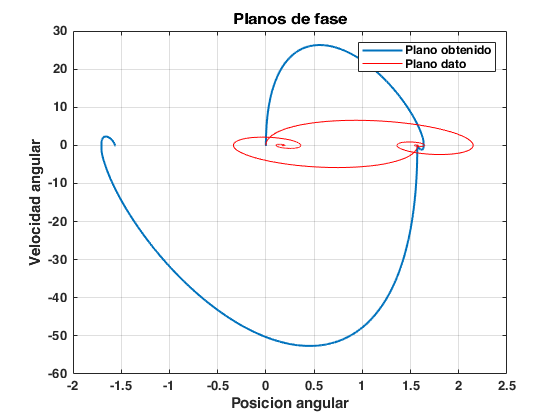

dead = ones(2,length(prevU));
dead(1,:) = dead(1,:)* deadZone;
dead(2,:) = dead(2,:)* (-1)*deadZone;
plot(t(1:length(prevU)),prevU,'LineWidth',1.5);
hold on;

plot(timeExcel,vExcel,'r');
plot(t(1:length(prevU)),dead,'k--');
hold off
xlim([0 T]);
grid;
title('Acción de control');
xlabel('Tiempo [seg]');
ylabel('Tension [V]');
legend('Accion de control obtenida','Accion de control dato','Umbral de zona muerta');

El plano de fases es el siguiente:

plot(x(3,:),x(2,:),'LineWidth',1.5);
hold on;
plot(angExcel,omegaExcel,'r');
hold off;

Ac =          0    1.0000         0         0
         0   -0.0667   -0.6533         0
         0         0         0    1.0000
         0   -0.0417   -6.5333         0


grid

Bc =          0
    0.6667
         0
    0.4167


xlabel('Posicion angular');
ylabel('Velocidad angular');
title('Planos de fase');
legend('Plano obtenido', 'Plano dato')

## Caso de estudio 3. Sistema no lineal de cuatro variables de estado.

clear all;
close all;
clc;

Se definen los parámetros del sistema:

m = 0.1;

sys1 =
 
  A = 
             x1        x2        x3        x4
   x1         0         1         0         0
   x2         0  -0.06667   -0.6533         0
   x3         0         0         0         1
   x4         0  -0.04167    -6.533         0
 
  B = 
           u1
   x1       0
   x2  0.6667
   x3       0
   x4  0.4167
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



F = 0.1;

dSys1 =
 
  A = 
               x1          x2          x3          x4
   x1           1    0.009997  -3.266e-05  -1.089e-07
   x2           0      0.9993    -0.00653  -3.266e-05
   x3           0  -2.083e-06      0.9997    0.009999
   x4           0  -0.0004165    -0.06532      0.9997
 
  B = 
              u1
   x1  3.333e-05
   x2   0.006664
   x3  2.083e-05
   x4   0.004165
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.



l = 1.6; 

A =     1.0000    0.0100   -0.0000   -0.0000
         0    0.9993   -0.0065   -0.0000
         0   -0.0000    0.9997    0.0100
         0   -0.0004   -0.0653    0.9997


g = 9.8;

B =     0.0000
    0.0067
    0.0000
    0.0042


M = 1.5;

Las matrices del sistema en tiempo continuo son:

Ac = [0 1 0 0; 0 -F/M -m*g/M 0; 0 0 0 1; 0 -F/(l*M) -g*(m+M)/(l*M) 0]
Bc = [0; 1/M; 0; 1/(l*M)]

Aamp1 =     1.0000    0.0100   -0.0000   -0.0000         0
         0    0.9993   -0.0065   -0.0000         0
         0   -0.0000    0.9997    0.0100         0
         0   -0.0004   -0.0653    0.9997         0
   -1.0000   -0.0100    0.0000    0.0000    1.0000


Cc = [1 0 0 0; 0 0 1 0];

Bamp1 =     0.0000
    0.0067
    0.0000
    0.0042
   -0.0000


Dc = [0];

Q1 =     0.1000         0         0         0         0
         0    0.0100         0         0         0
         0         0    1.0000         0         0
         0         0         0    0.1000         0
         0         0         0         0    0.0000


Los tiempos que se manejarán son:

Ts = 1e-2;          
T = 25;            
At = 1e-4;          

Kp1 =    40.7242   29.6109   78.8271  -12.0997


Kmax = T/Ts;

Kint1 = 0.2047

Se obtiene el sistema de tiempo continuo para luego discretizar.

sys1 = ss(Ac, Bc, Cc, Dc)
dSys1 = c2d(sys1,Ts,'zoh')

Ac2 =          0    1.0000         0         0
         0   -0.0667   -6.5333         0
         0         0         0    1.0000
         0   -0.0417  -10.2083         0


A = dSys1.A

sys2 =
 
  A = 
             x1        x2        x3        x4
   x1         0         1         0         0
   x2         0  -0.06667    -6.533         0
   x3         0         0         0         1
   x4         0  -0.04167    -10.21         0
 
  B = 
           u1
   x1       0
   x2  0.6667
   x3       0
   x4  0.4167
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Continuous-time state-space model.



B = dSys1.B

dSys2 =
 
  A = 
               x1          x2          x3          x4
   x1           1    0.009997  -0.0003266  -1.089e-06
   x2           0      0.9993     -0.0653  -0.0003266
   x3           0  -2.083e-06      0.9995    0.009998
   x4           0  -0.0004165     -0.1021      0.9995
 
  B = 
              u1
   x1  3.332e-05
   x2   0.006664
   x3  2.083e-05
   x4   0.004165
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
   y2   0   0   1   0
 
  D = 
       u1
   y1   0
   y2   0
 
Sample time: 0.01 seconds
Discrete-time state-space model.



Se implementa un integrador para medir el desplazamiento:

Cref = Cc(1,:);

A2 =     1.0000    0.0100   -0.0003   -0.0000
         0    0.9993   -0.0653   -0.0003
         0   -0.0000    0.9995    0.0100
         0   -0.0004   -0.1021    0.9995


Aamp1 = [A,zeros(4,1);-Cref*A,eye(1)]

B2 =     0.0000
    0.0067
    0.0000
    0.0042


Bamp1 = [B;-Cref*B]

Aamp2 =     1.0000    0.0100   -0.0003   -0.0000         0
         0    0.9993   -0.0653   -0.0003         0
         0   -0.0000    0.9995    0.0100         0
         0   -0.0004   -0.1021    0.9995         0
   -1.0000   -0.0100    0.0003    0.0000    1.0000


Q1 = diag([.1 1e-2 1 .1 0.0000093])

Q2 =     0.1000         0         0         0         0
         0    0.0100         0         0         0
         0         0    1.0000         0         0
         0         0         0    0.1000         0
         0         0         0         0    0.0000


R1 = 1.9e-4;
K1 = dlqr(Aamp1,Bamp1,Q1,R1);

K2 =    26.2505   19.7487   42.3199   -6.6219   -0.1292


Kp1 = K1(1:4)

Kp2 =    26.2505   19.7487   42.3199   -6.6219


Kint1 = -K1(5)

Kint2 = 0.1292

Ahora, para cuando la masa aumente en 10 veces, se plantea otro controlador.

m1 = 10*m;

Ao =     1.0000         0         0         0
    0.0100    0.9993   -0.0000   -0.0004
   -0.0000   -0.0065    0.9997   -0.0653
   -0.0000   -0.0000    0.0100    0.9997


Ac2 = [0 1 0 0; 0 -F/M -m1*g/M 0; 0 0 0 1; 0 -F/(l*M) -g*(m1+M)/(l*M) 0]

Bo =      1     0
     0     0
     0     1
     0     0


sys2 = ss(Ac2,Bc,Cc,Dc)

Co =     0.0000    0.0067    0.0000    0.0042


dSys2 = c2d(sys2,Ts,'zoh')

Qo = 	1.0e+03 *

    0.0000         0         0         0
         0    1.0000         0         0
         0         0    0.0005         0
         0         0         0    0.0000


A2 = dSys2.A

Ro =           80           0
           0       10000


B2 = dSys2.B
Aamp2 = [A2,zeros(4,1);-Cref*A2,eye(1)]

Ko =     0.2641   -0.0000
    3.0782   -0.0004
   -0.0018    0.0070
   -0.0102   -0.0005


Q2 = diag([.1 1e-2 1 .1 0.0000093])
R2 = 0.0005;
K2 = dlqr(Aamp2,Bamp1,Q2,R2)
Kp2 = K2(1:4)
Kint2 = -K2(5)

El observador, a continuacion:

Ao = A'
Bo = Cc'
Co = B'
Qo = diag([0.001 1000 0.5 0.0001])
Ro = diag([80 10000])
Ko = dlqr(Ao,Bo,Qo,Ro);
Ko = Ko'

Para poder simular, se plantean las siguientes variables:

phi(1) = pi; 
x = [0;0;phi(1);0];
delta = x(1);
deltaP = x(2);
phi = x(3);
omega = x(4);

phiPP(1) = 0;
h = Ts/20;
i = 1;
deltaRef = 10; 
bool = 0;
v(1) = 0;
xHat = [0;0;pi;0];
xOp=[0 0 pi 0]';
reference(1) = 10;

Simulacion:

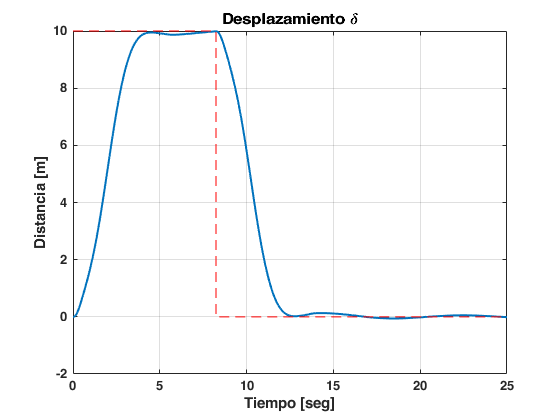

K = Kp1;
KI = Kint1;
for index=1:Kmax
    yOut = Cc*x;  
    yOutObs = Cc*(xHat-xOp);
    v(index+1) = v(index)+deltaRef-yOut(1);
    u1(index) = -K*(x-xOp)+KI*v(index+1); 
    deadZone = 1;
    if(abs(u1(index)) < deadZone)
        u1(index) = 0;               
    else

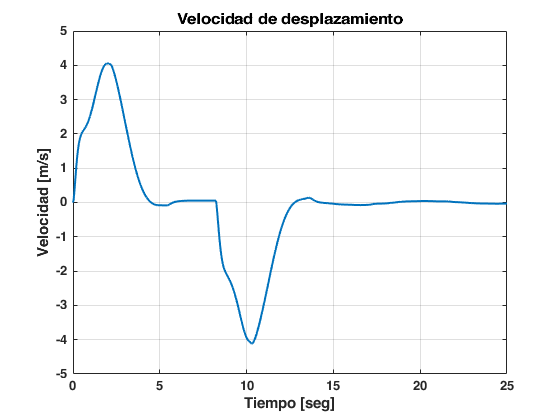

        u1(index)=sign(u1(index))*(abs(u1(index))-deadZone);
    end
    for j=1:Ts/h
        u(i) = u1(index);
        p_pp = (1/(M+m))*(u(i)-m*l*phiPP*cos(phi(i))+m*l*omega(i)^2*sin(phi(i))-F*deltaP(i));

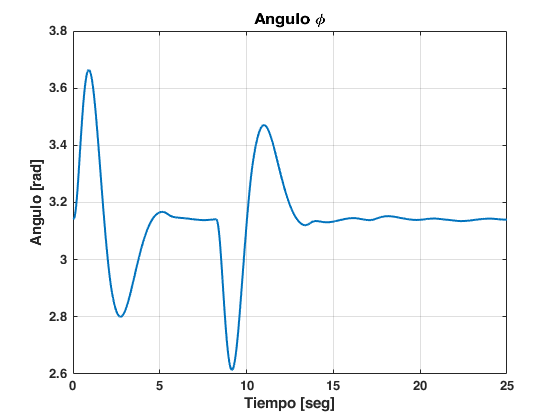

        phiPP = (1/l)*(g*sin(phi(i))-p_pp*cos(phi(i)));
        deltaP(i+1) = deltaP(i)+h*p_pp;
        delta(i+1) = delta(i)+h*deltaP(i);
        omega(i+1) = omega(i)+h*phiPP;
        phi(i+1) = phi(i)+h*omega(i);

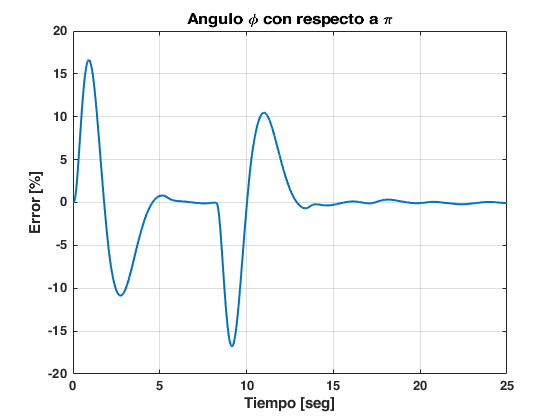

        if(delta(i) >= 9.99)
            if(bool == 0)
                deltaRef = 0;
                m = m*10;
                bool = 1;

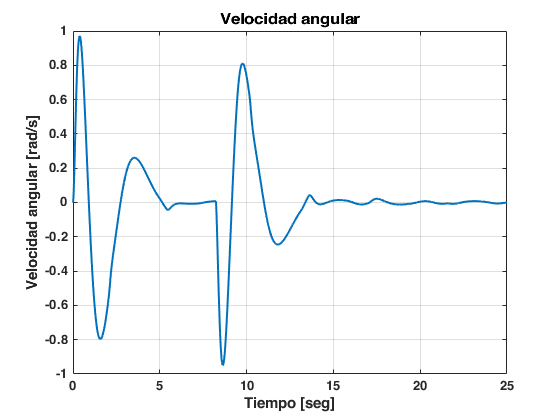

                K = Kp2;
                KI = Kint2;
            end
        end
        i = i+1;

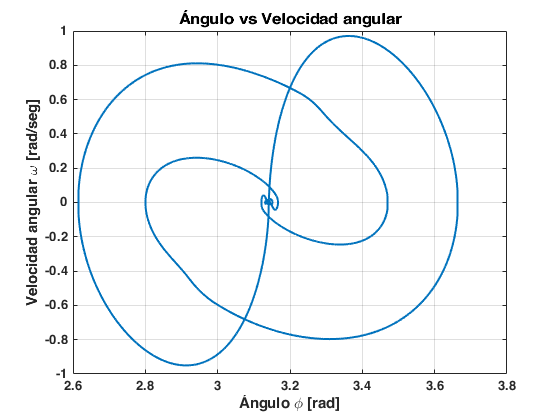

        reference(i) = deltaRef;
    end
    x = [delta(i-1); deltaP(i-1); phi(i-1); omega(i-1)];
    xHat = A*xHat+B*u1(index)+Ko*(yOut-yOutObs)+xOp;
end
u(i) = u1(index);

t = 0:h:T;

Se muestran las gráficas obtenidas:

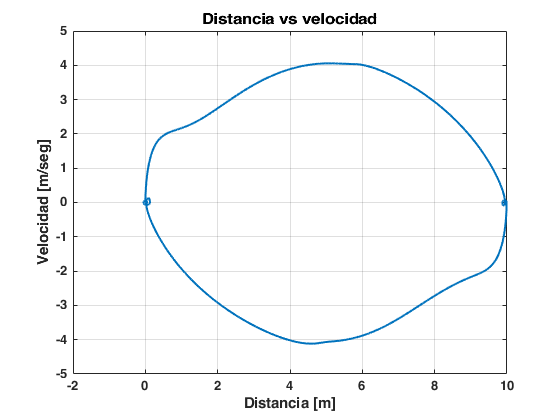

plot(t,delta,'LineWidth',1.5);
hold on;
plot(t,reference,'r--')
hold off;

grid; 
title('Desplazamiento \delta');
xlabel('Tiempo [seg]')
ylabel('Distancia [m]')
plot(t,deltaP,'LineWidth',1.5);
grid;
title('Velocidad de desplazamiento')
xlabel('Tiempo [seg]')
ylabel('Velocidad [m/s]')
plot(t,phi,'LineWidth',1.5);
grid;
title('Angulo \phi')
xlabel('Tiempo [seg]')
ylabel('Angulo [rad]')
plot(t,phi/pi*100-100,'LineWidth',1.5);
grid;
title('Angulo \phi con respecto a \pi')
xlabel('Tiempo [seg]')
ylabel('Error [%]')
plot(t,omega,'LineWidth',1.5);
grid;
title('Velocidad angular')
xlabel('Tiempo [seg]')
ylabel('Velocidad angular [rad/s]')

Los planos de fase son los siguientes:

plot(phi,omega,'LineWidth',1.5);
title('Ángulo vs Velocidad angular');
xlabel('Ángulo \phi [rad]');
ylabel('Velocidad angular \omega [rad/seg]');
grid;
plot(delta,deltaP,'LineWidth',1.5);
title('Distancia vs velocidad');
xlabel('Distancia [m]');
ylabel('Velocidad [m/seg]');
grid;